# Feature 추출하기  

- extract_feature_v1 를 사용

- 기본 raw 데이타를 추출함

시계열 데이타이지만 각 피쳐와 Capacity는  시계열 모델이 아니라 일반적인 structural 모델이다.

실험결과 선택한 feature 에 따른 선형관계이므로 선택한 feature 의 outer는 제외시켜야 한다.

load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat
BAT1 =B0005;
BAT2 =B0006;
BAT3 =B0007; 
BAT4 =B0018; 


## 피쳐 얻어오기

array2table 로 테이블을 만들때 선형회구를 하기 위해 종속변수를 제일 뒤에 두어라

[cap,maxTemp,maxTimeDelta,abnormal,ohm,re_c,re_d] = extract_feature_v1(BAT1);
%https://kr.mathworks.com/help/matlab/ref/find.html
k = find(abnormal) 

k =      1    33


% https://kr.mathworks.com/help/matlab/ref/interp1.html

% 빈공간을 채우는 방법이다.

%https://kr.mathworks.com/help/matlab/ref/filloutliers.html

# filloutliers

데이터에서 이상값 감지하고 바꾸기

`fillmethod` **—** **채우기 방법**

숫자형 스칼라 | `'center'` | `'clip'` | `'previous'` | `'next'` | `'nearest'` | `'linear'` | `'spline'` | `'pchip'` | `'makima'`

이상값을 바꾸기 위한 채우기 방법으로, 숫자형 스칼라나 다음 중 하나로 지정됩니다.

**채우기 방법****설명**

숫자형 스칼라지정된 스칼라 값으로 채웁니다.

`'center'``findmethod`로 결정된 중심값으로 채웁니다.

`'clip'``findmethod`로 결정된 하한 임계값보다 작은 요소에 대해 하한 임계값으로 채웁니다. `findmethod`로 결정된 상한 임계값보다 큰 요소에 대해 상한 임계값으로 채웁니다.

`'previous'`이상값이 아닌 이전 값으로 채웁니다.

`'next'`이상값이 아닌 다음 값으로 채웁니다.

`'nearest'`이상값이 아닌 가장 가까운 값으로 채웁니다.

`'linear'`이상값이 아닌 인접 값의 선형 보간을 사용하여 채웁니다.

`'spline'`조각별 3차 스플라인 보간을 사용하여 채웁니다.

`'pchip'`형태 보존 조각별 3차 스플라인 보간을 사용하여 채웁니다.

`'makima'`아키마 3차 에르미트 다항식 변형 보간(숫자형, `duration` 및 `datetime` 데이터형에만 해당)

**데이터형:** `double` | `single` | `char`

`findmethod` **—** **이상값 감지 방법**

`'median'` (디폴트 값) | `'mean'` | `'quartiles'` | `'grubbs'` | `'gesd'`

이상값 감지 방법으로, 다음 중 하나로 지정됩니다.

**메서드****설명**

`'median'`중앙값에서 스케일링된 3 중앙값 절대 편차(MAD)를 초과하여 떨어져 있는 요소로 이상값이 정의됩니다. 스케일링된 MAD는 `c*median(abs(A-median(A)))`로 정의됩니다. 여기서 `c=-1/(sqrt(2)*erfcinv(3/2))`입니다.

`'mean'`평균에서 3 표준편차를 초과하여 떨어져 있는 요소로 이상값이 정의됩니다. 이 방법은 `'median'`보다 빠르지만 덜 견고합니다.

`'quartiles'`상한 사분위수(75%)를 기준으로 1.5 사분위 범위보다 크거나 하한 사분위수(25%)를 기준으로 1.5 사분위 범위보다 작은 요소로 이상값이 정의됩니다. 이 방법은 `A`의 데이터가 정규분포되지 않은 경우에 유용합니다.

`'grubbs'`가설검정을 기반으로 이상값 1개를 매회 제거하는 그럽스 검정(Grubbs test)을 사용하여 이상값을 감지합니다. 이 방법에서는 `A`의 데이터가 정규분포된 것으로 가정합니다.

`'gesd'`이상값에 대해 일반화된 극단적 스튜던트화 이탈(Extreme Studentized Deviate) 검정을 사용하여 이상값을 감지합니다. 이 반복법은 `'grubbs'`와 유사하지만, 서로를 감추는 여러 이상값이 있는 경우 더 효율적일 수 있습니다.

cycle_num = size(maxTimeDelta,2)

cycle_num = 169


fix_linear = filloutliers(maxTimeDelta,'linear')

fix_linear = 	1.0e+03 *

    0.8698    3.4476    3.4192    3.4216    3.3951    3.4220    3.4373    3.4240    3.3937    3.4014    3.4112    3.4033    3.0994    3.3988    3.3970    3.4119    3.3491    3.3285    3.3669    3.3392    3.3198    3.4947    3.4638    3.4567    3.4039    3.4200    3.3979    3.3850    3.3860    3.3882    3.3633    3.3879    3.3927    3.3975    3.3809    3.3403    3.3225    3.2694    3.2979    3.2370    3.2608    3.2399    3.2014    3.2095    3.1987    3.1909    3.1642    3.1556    3.1331    3.1071


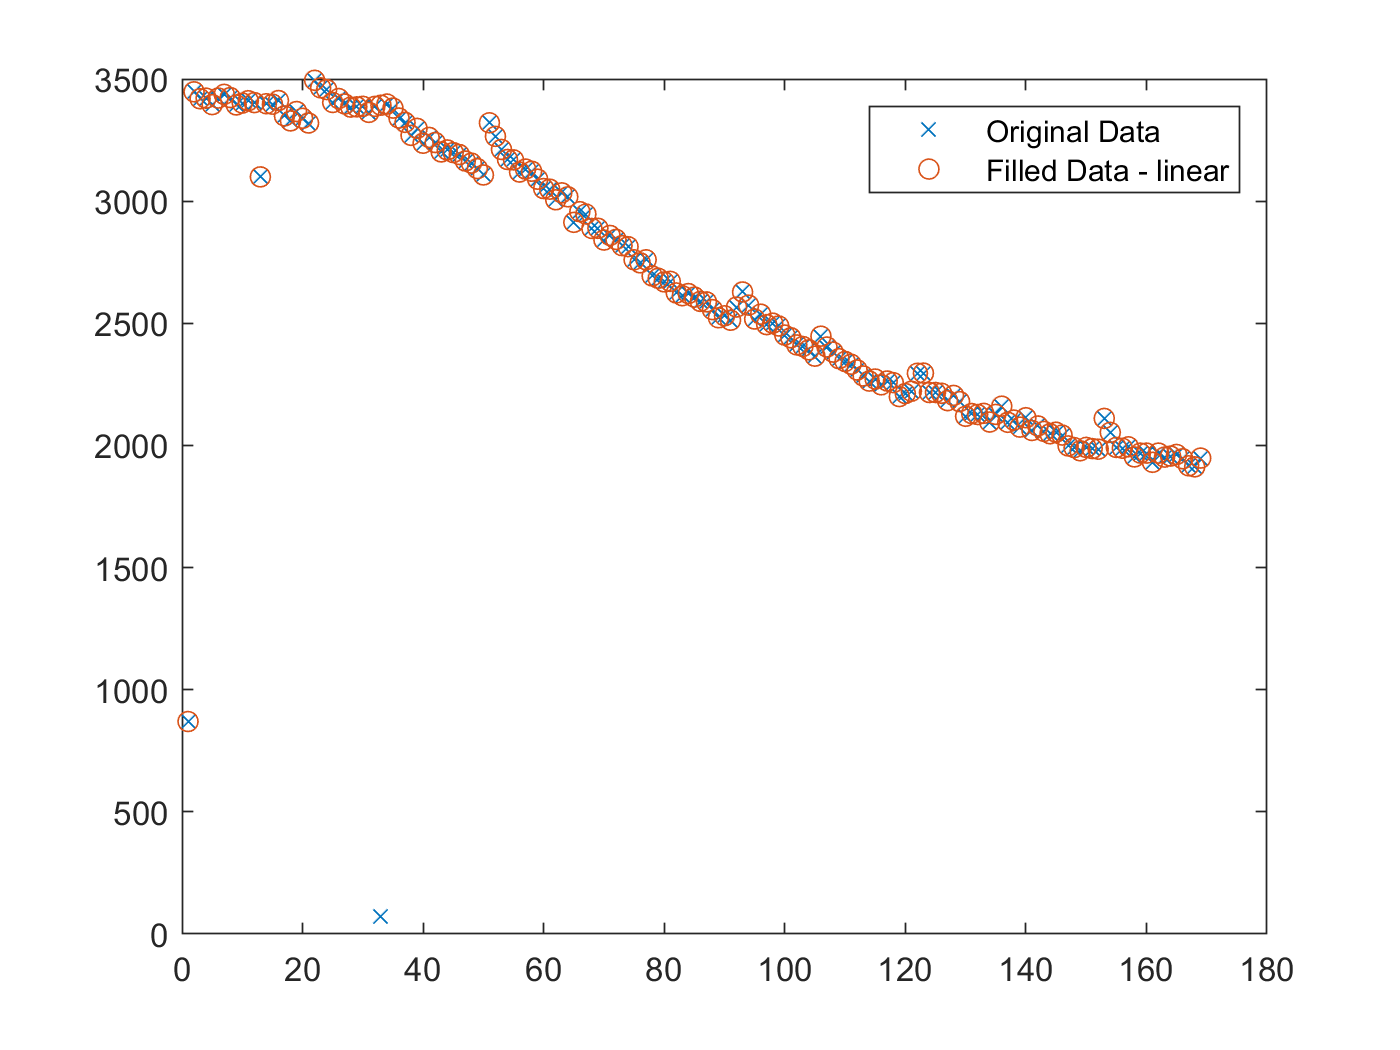

plot(1:cycle_num,maxTimeDelta,'x',1:cycle_num,fix_linear,'o')
legend('Original Data','Filled Data - linear')


fix_nearest_mean = filloutliers(maxTimeDelta,'nearest','mean')

fix_nearest_mean = 	1.0e+03 *

    3.4476    3.4476    3.4192    3.4216    3.3951    3.4220    3.4373    3.4240    3.3937    3.4014    3.4112    3.4033    3.0994    3.3988    3.3970    3.4119    3.3491    3.3285    3.3669    3.3392    3.3198    3.4947    3.4638    3.4567    3.4039    3.4200    3.3979    3.3850    3.3860    3.3882    3.3633    3.3879    3.3975    3.3975    3.3809    3.3403    3.3225    3.2694    3.2979    3.2370    3.2608    3.2399    3.2014    3.2095    3.1987    3.1909    3.1642    3.1556    3.1331    3.1071


fix_nearest_median = filloutliers(maxTimeDelta,'nearest','median')

fix_nearest_median = 	1.0e+03 *

    0.8698    3.4476    3.4192    3.4216    3.3951    3.4220    3.4373    3.4240    3.3937    3.4014    3.4112    3.4033    3.0994    3.3988    3.3970    3.4119    3.3491    3.3285    3.3669    3.3392    3.3198    3.4947    3.4638    3.4567    3.4039    3.4200    3.3979    3.3850    3.3860    3.3882    3.3633    3.3879    3.3975    3.3975    3.3809    3.3403    3.3225    3.2694    3.2979    3.2370    3.2608    3.2399    3.2014    3.2095    3.1987    3.1909    3.1642    3.1556    3.1331    3.1071


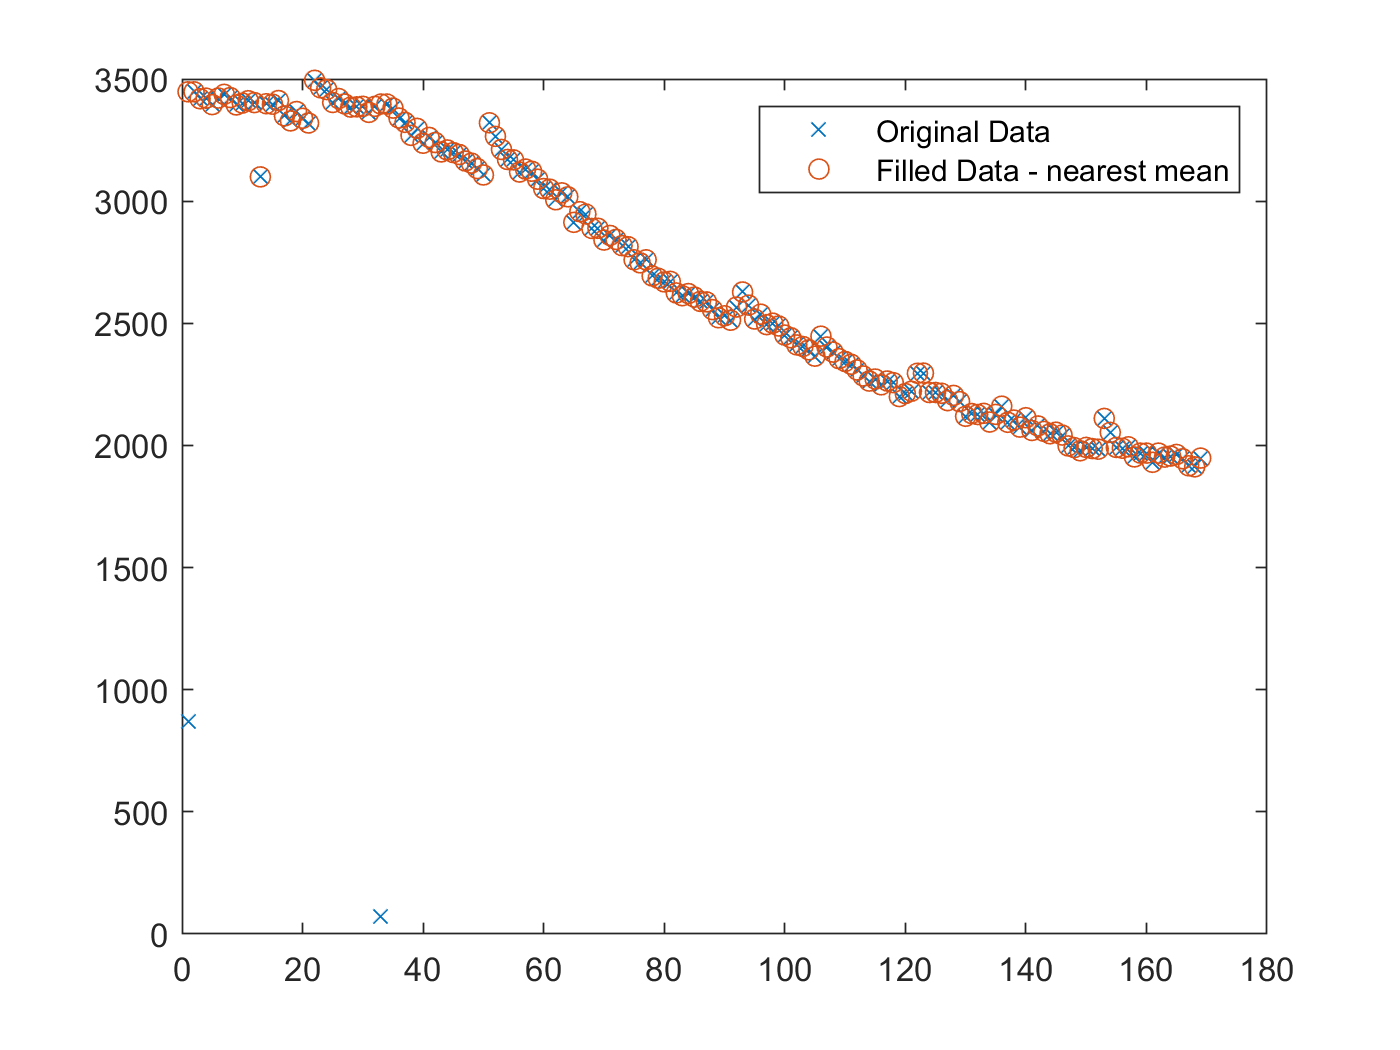


plot(1:cycle_num,maxTimeDelta,'x',1:cycle_num,fix_nearest_mean,'o')
legend('Original Data','Filled Data - nearest mean')

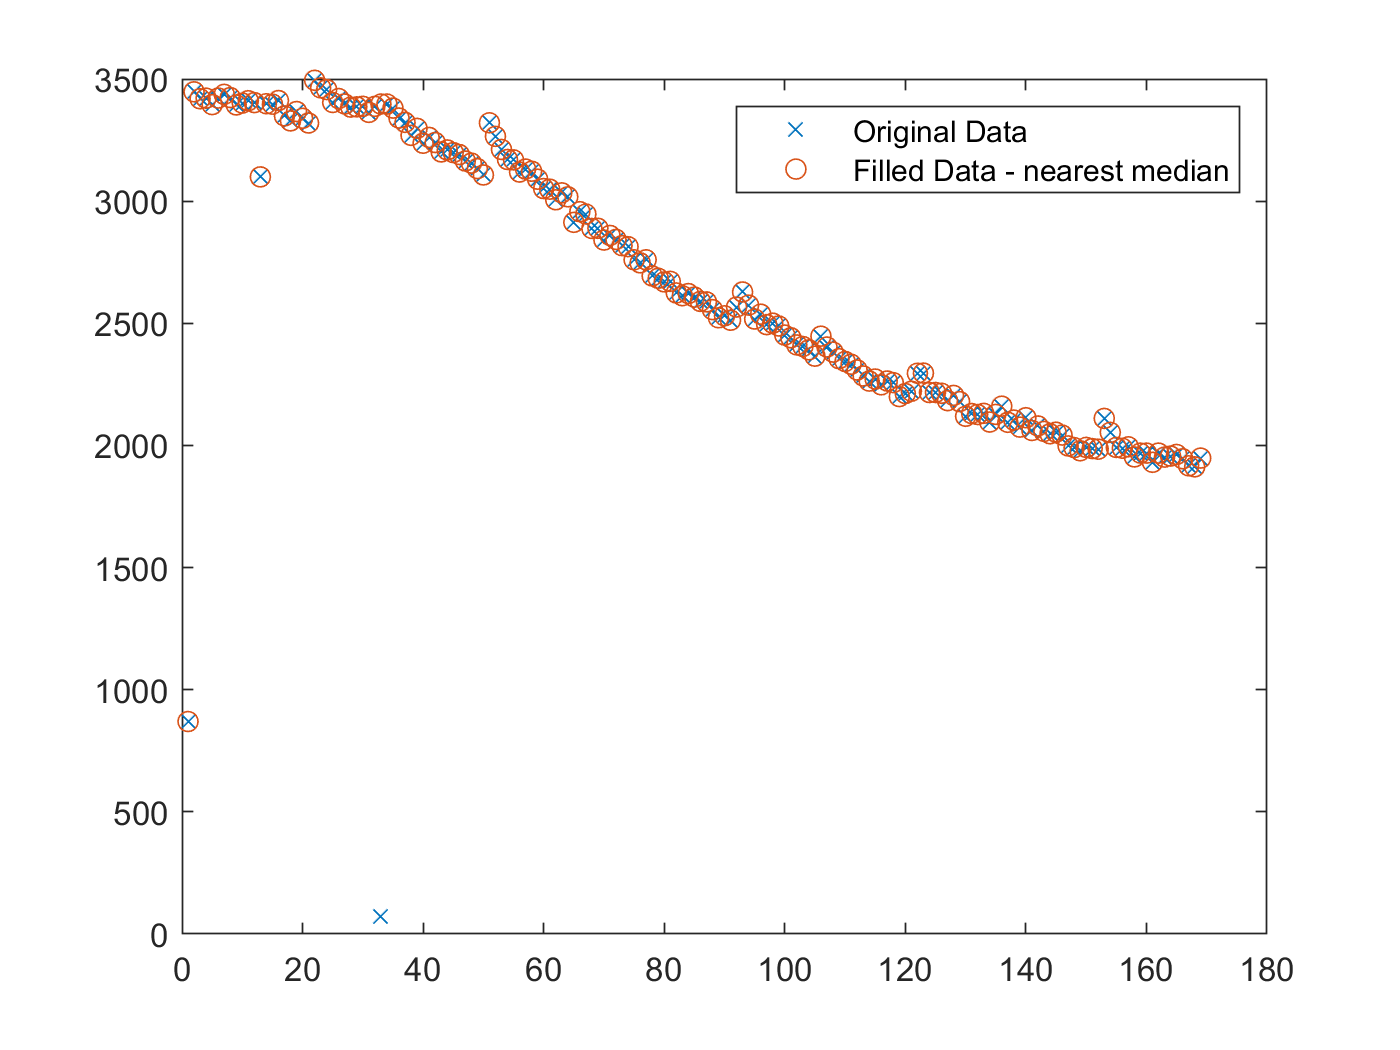

plot(1:cycle_num,maxTimeDelta,'x',1:cycle_num,fix_nearest_median,'o')
legend('Original Data','Filled Data - nearest median')

#### 이것이 내가 생각하는 것이랑 가장 비슷하게 동작한다.

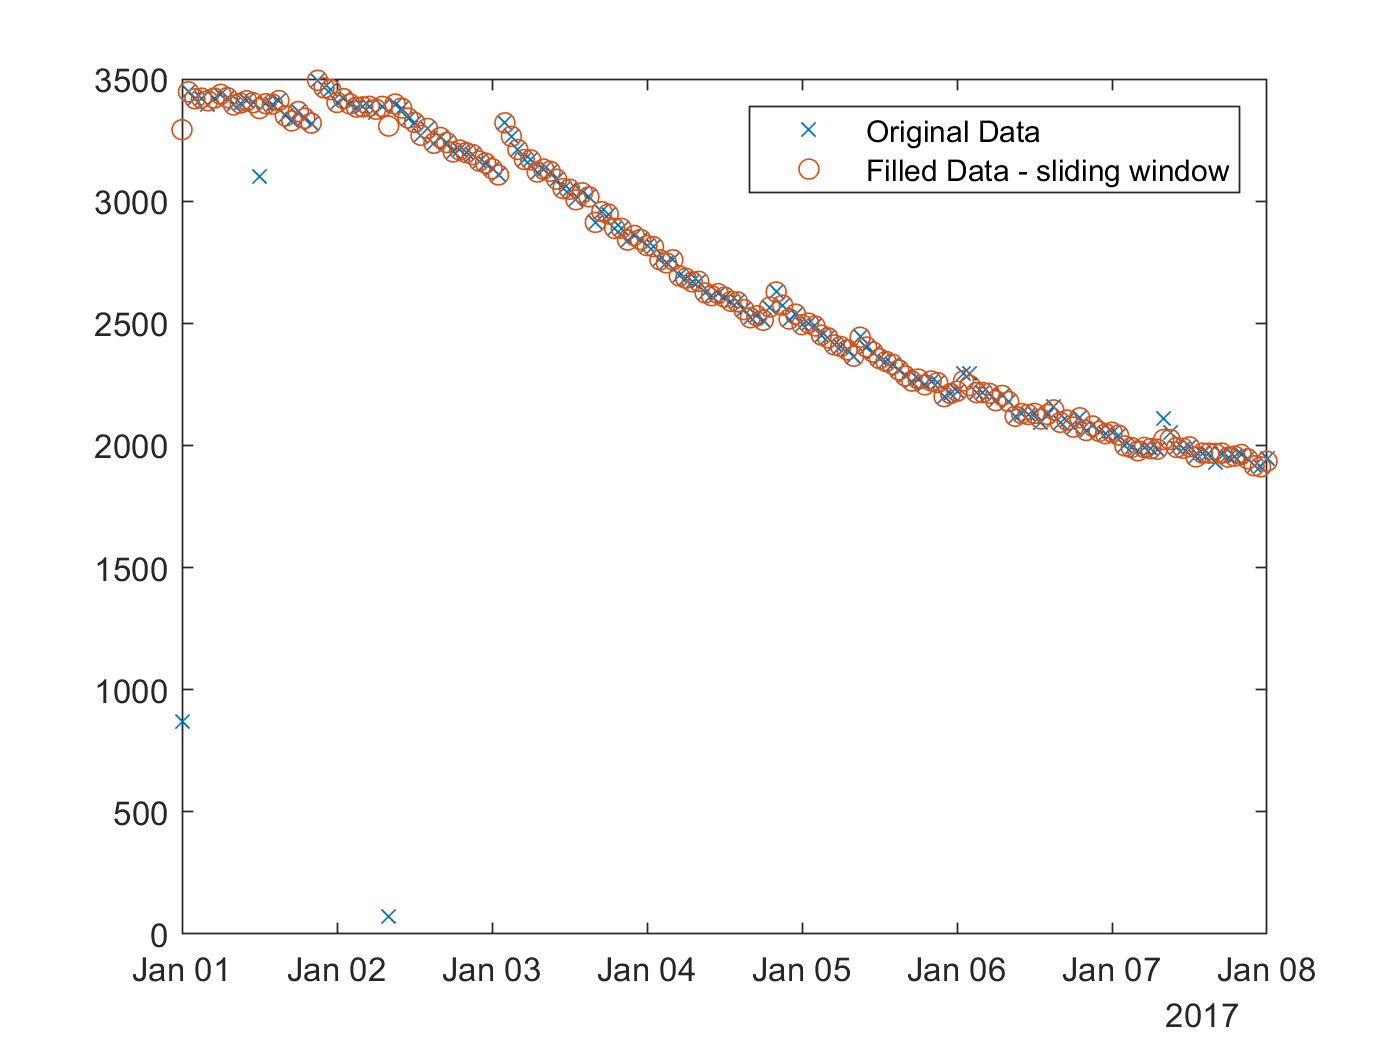

t = datetime(2017,1,1,0,0,0) + hours(0:length(maxTimeDelta)-1);
[maxTimeDelta_adj,TF,U,L,C] = filloutliers(maxTimeDelta,'clip','movmedian',hours(5),'SamplePoints',t);
plot(t,maxTimeDelta,'x',t,maxTimeDelta_adj,'o')
legend('Original Data','Filled Data - sliding window')


%maxTimeDelta(abnormal) <= 이상값을 변경하는 것도 필요하다. 차후에.
dataVectorAll = [  maxTimeDelta' maxTemp' ohm'  re_c' re_d' cap'];
dataVector = [  maxTimeDelta' cap'];

dataVectorAll_adj = [  maxTimeDelta_adj' maxTemp' ohm'  re_c' re_d' cap'];
dataVector_adj = [  maxTimeDelta_adj' cap'];

[cap2,maxTemp2,maxTimeDelta2,abnormal2,ohm2,re_c2,re_d2] = extract_feature_v1(BAT2);
dataVectorAll2 = [maxTimeDelta2' maxTemp2' ohm2'  re_c2' re_d2' cap2'  ];
dataVector2 = [maxTimeDelta2' cap2'  ];

[cap3,maxTemp3,maxTimeDelta3,abnormal3,ohm3,re_c3,re_d3] = extract_feature_v1(BAT3);
dataVectorAll3 = [maxTimeDelta3' maxTemp3' ohm3'  re_c3' re_d3' cap3'  ];
dataVector3 = [maxTimeDelta3'  cap3'  ];

%{
% extract_feature function has errors on BAT4
[cap4,maxTemp4,maxTimeDelta4,abnormal4,ohm4,re_c4,re_d4] = extract_feature_v1(BAT4);
dataVectorAll4 = [maxTimeDelta4' maxTemp4' ohm4'  re_c4' re_d4' cap4'  ];
dataVector4 = [maxTimeDelta4' cap4'  ];
%}

#### 플롯

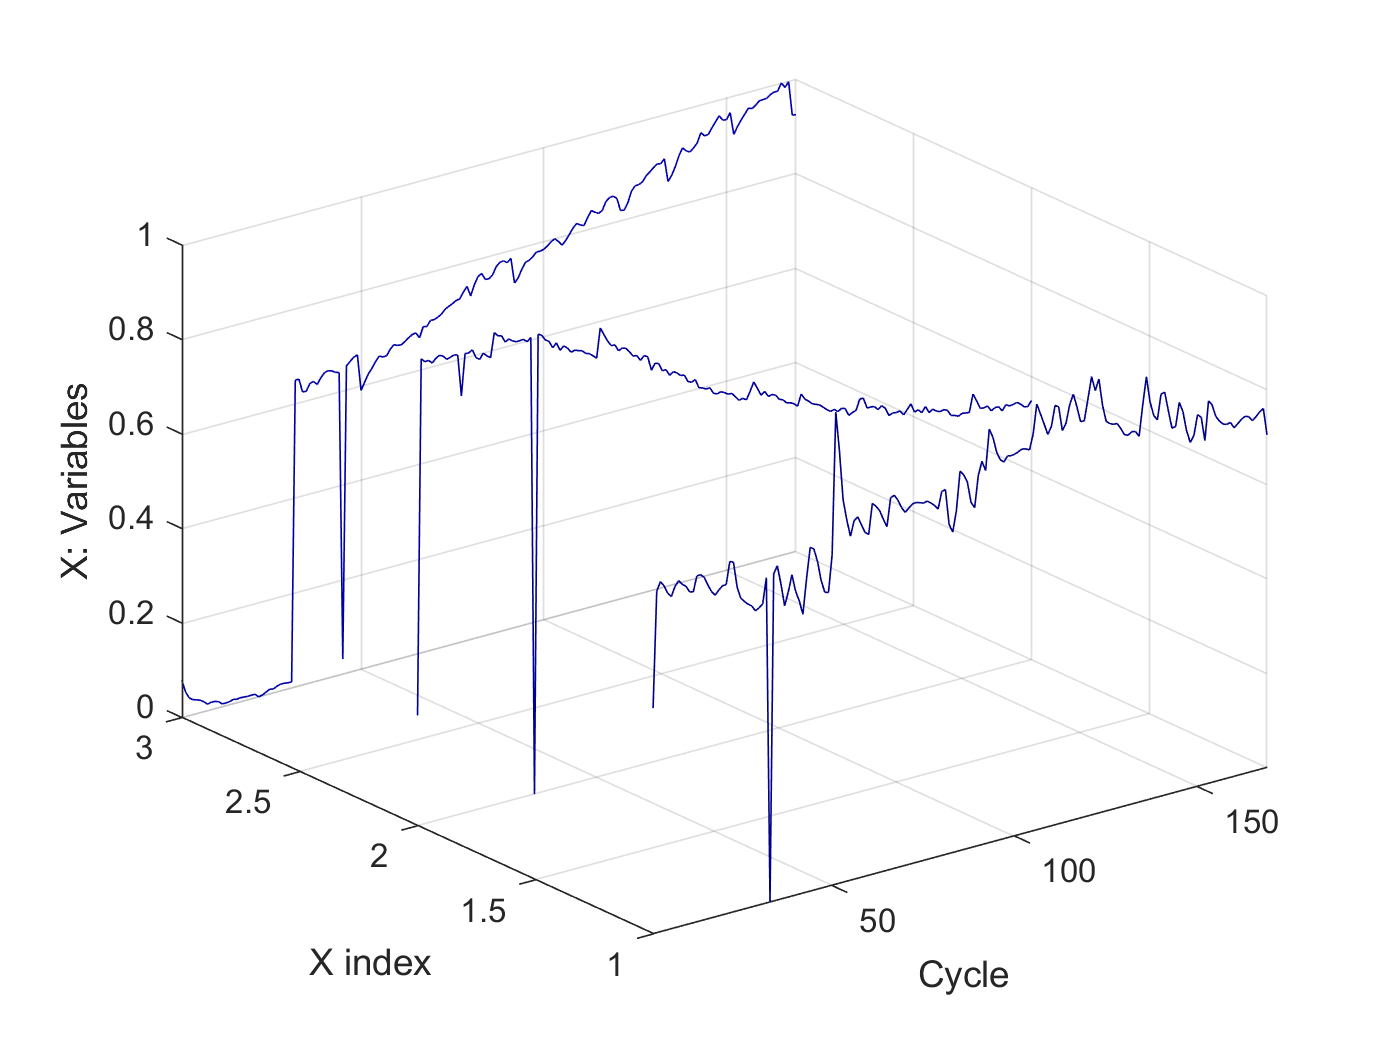

% 주성분 분석은 독립변수로만
X_vars =  [maxTemp' maxTimeDelta' ohm' ];
%X_vars =   maxTimeDelta';
Y_vars = cap';

nCycle = 169; %60
nX = size(X_vars,2); % 401
%nX = 1;


[dummy,h] = sort(Y_vars);
oldorder = get(gcf,'DefaultAxesColorOrder');
set(gcf,'DefaultAxesColorOrder',jet(60));

% https://kr.mathworks.com/matlabcentral/answers/329299-how-to-normalize-vector-to-unit-length
% do normalize to plot
R = X_vars; 
Rmax = repmat(max(R), size(R,1), 1);
Rmin = repmat(min(R), size(R,1), 1);
R_unity = (R - Rmin)./(Rmax - Rmin);
    
plot3(repmat(1:nCycle,nX,1)',repmat(1:nX,nCycle,1),R_unity );
%plot3(repmat(1:nCycle,nX,1)',repmat(1:nCycle,nX,1),X_vars );
% ,repmat(Y_vars(h),1,nX) 
%plot3(repmat(1:401,60,1)',repmat(octane(h),1,401)',NIR(h,:)');

set(gcf,'DefaultAxesColorOrder',oldorder);
xlabel('Cycle'); ylabel('X index');  zlabel('X: Variables'); axis('tight');
grid on

#### 백터를 테이블로 저장하기


tbl = array2table(dataVector,...
    'VariableNames',{'maxTimeDelta','cap'});
tbl_adj = array2table(dataVector_adj,...
    'VariableNames',{'maxTimeDelta','cap'});
[R,PValue] = corrplot(dataVector,'type','Pearson','testR','on','varNames',{'maxTimeDelta','Capacity'});
[R,PValue] = corrplot(dataVector_adj,'type','Pearson','testR','on','varNames',{'maxTimeDelta','Capacity'});


#### 참조문서

C:\nobackup\Downloads\Xu_2018_IOP_Conf._Ser.__Mater._Sci._Eng._452_032067.pdf

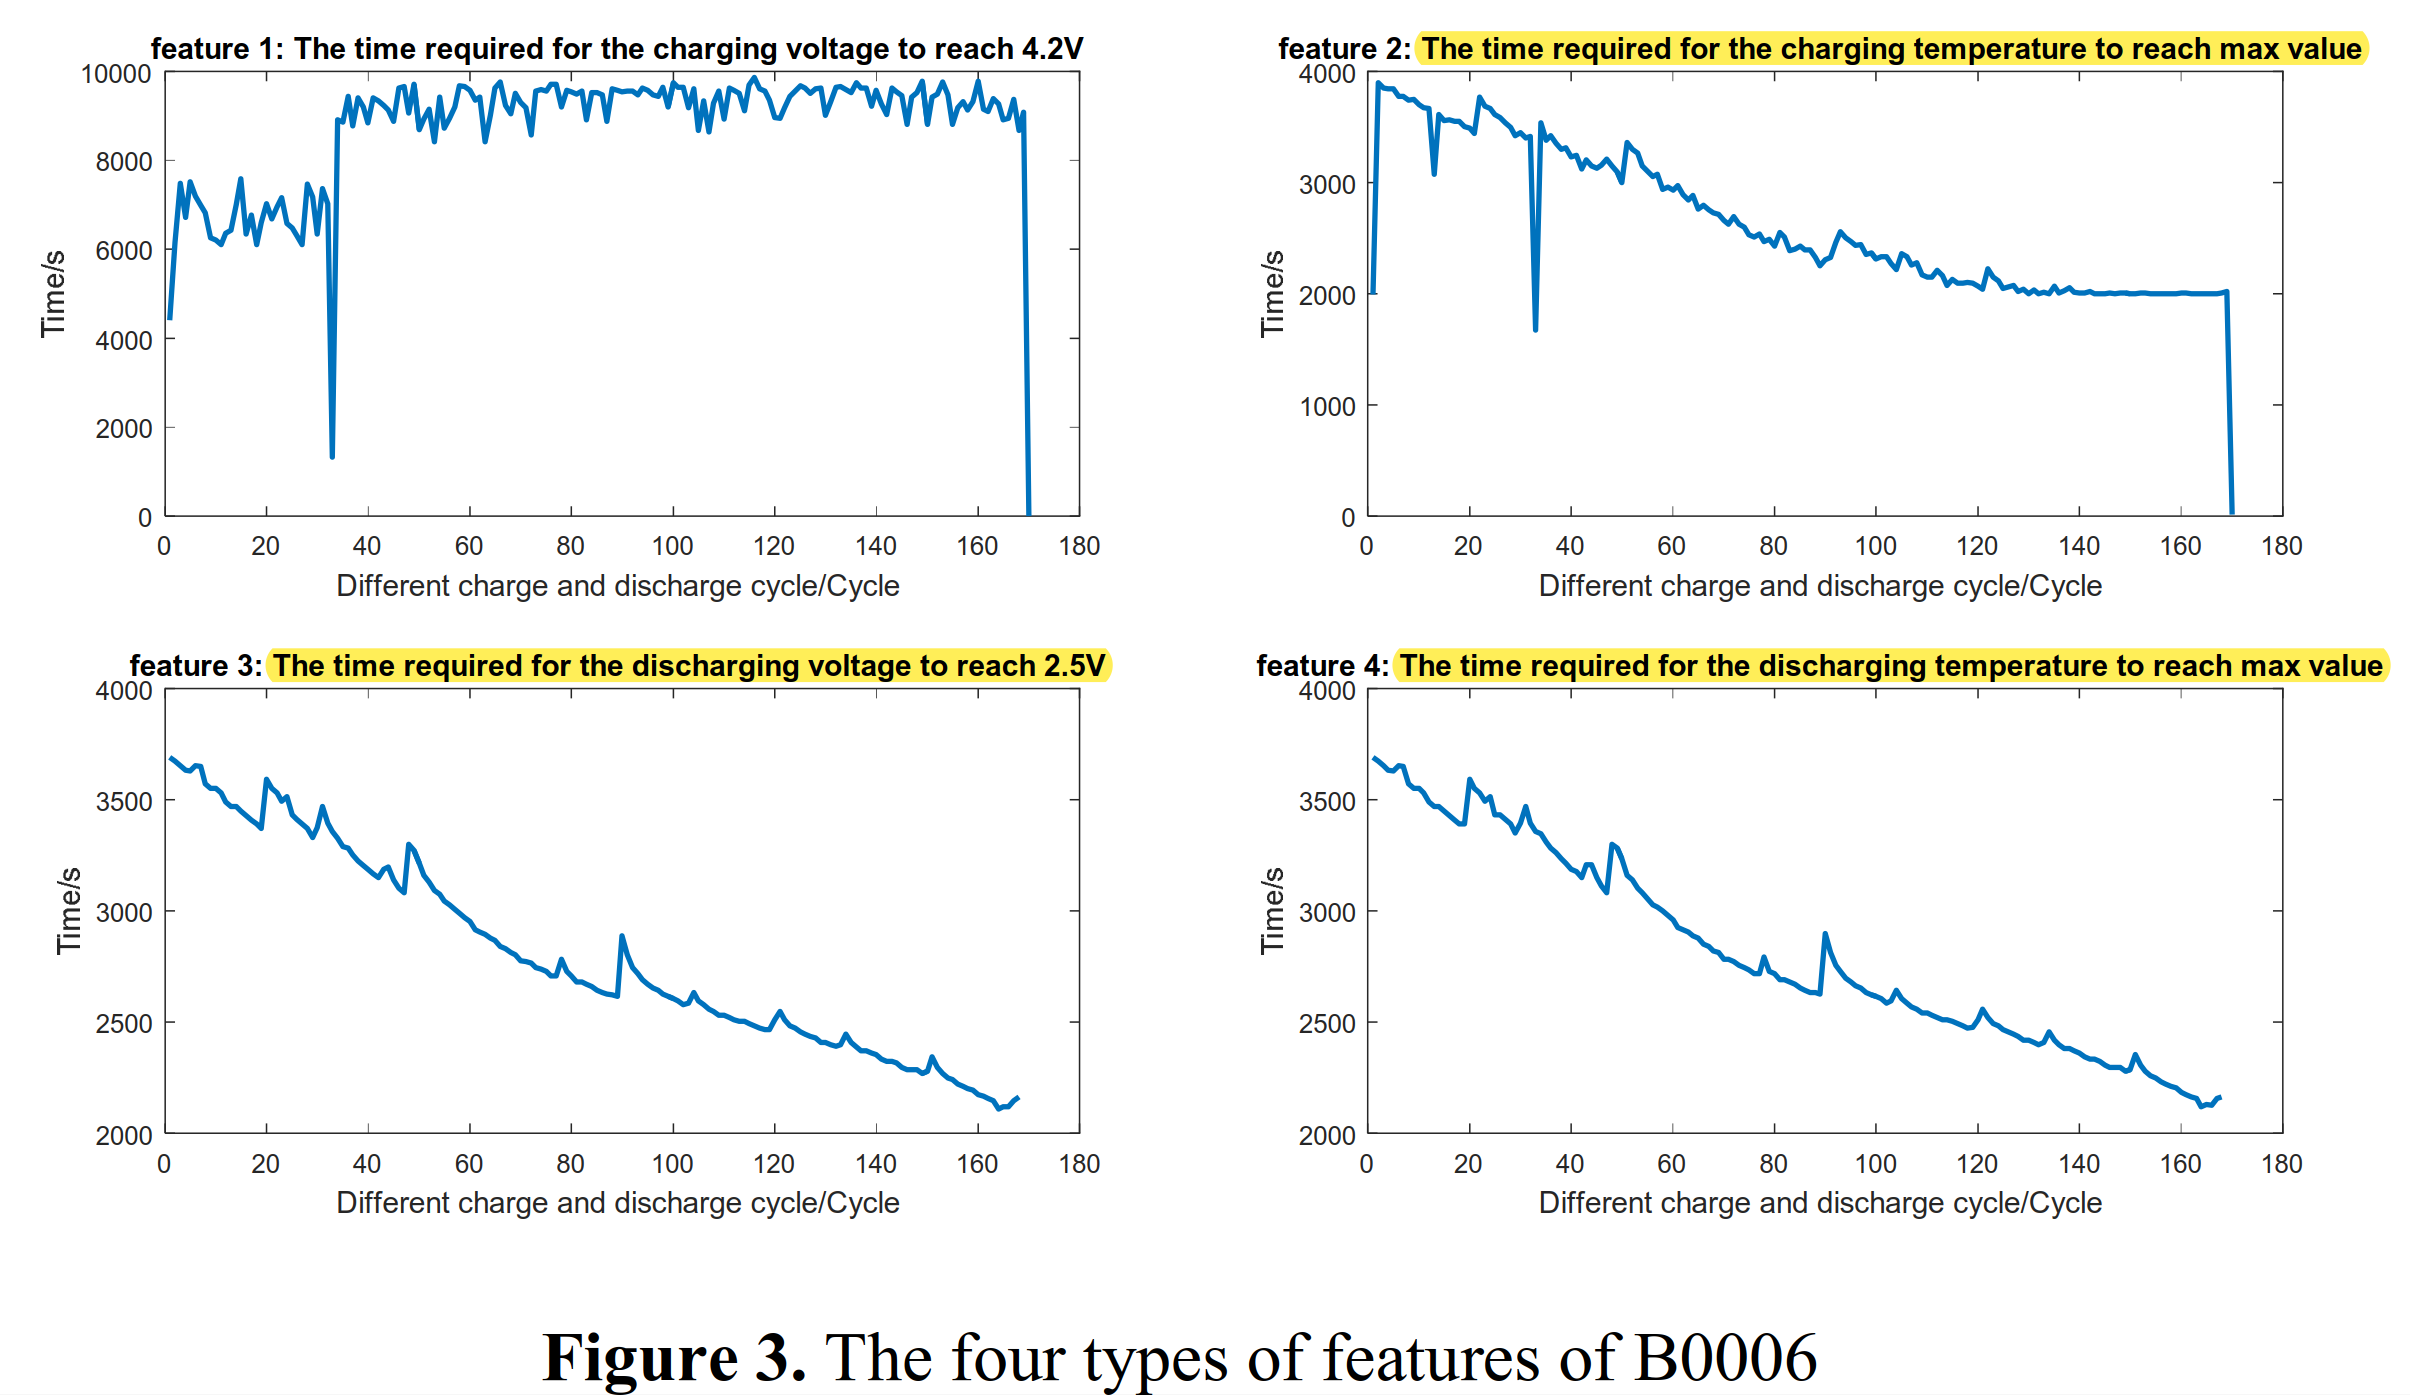

#### 선형회귀에 적용하기


% https://kr.mathworks.com/help/stats/fitlm.html
modelspec = ' cap ~ maxTimeDelta ';
mdl = fitlm(tbl,modelspec )
mdl_adj = fitlm(tbl_adj,modelspec )
mdl.Coefficients
mdl_adj.Coefficients
% https://kr.mathworks.com/help/stats/linearmodel.plot.html
plot(mdl)
plot(mdl_adj)

모델링된 선형회구식을 가지고 원래 데이타와 예측한 데이타를 비교하자

차이가 많이 난다.

cap5 = cap;
cap5hat = table2array(mdl.Coefficients(1,1)) ...
    + table2array(mdl.Coefficients(2,1))*maxTimeDelta ;
cap5hat_adj = table2array(mdl_adj.Coefficients(1,1)) ...
    + table2array(mdl_adj.Coefficients(2,1))*maxTimeDelta ;

figure
plot(cap5), hold on, plot(cap5hat','-'),plot(cap5hat_adj,'--')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 raw', 'Battery #5 pred', 'Battery #5 pred adj','Failure Threshold')
title('Capacity Degradations in Cycle - raw , pred, pred adj ')



모델설정후 잔차에 대한 히스토그램을 그린다.

plotResiduals(mdl)
plotResiduals(mdl_adj)

전차가 큰 것이 두개가 보인다. 이를 제거하자

outlier = mdl.Residuals.Raw > 0.2;
find(outlier)

모델에 사용된 데이타에서 outer 를 제외하고 모델링하라.

mdl1 = fitlm(tbl,modelspec,...
    'Exclude',find(outlier));

outer 정보 출력

mdl1.ObservationInfo(find(outlier),:)

outer를 제거 후 회귀선이 잘 그려지는지 확인하자.

plot(mdl1)

모델링된 선형회구식을 가지고 원래 데이타와 예측한 데이타를 비교하자

차기가 많이 줄어들었다.


cap5hat = table2array(mdl1.Coefficients(1,1)) ...
    + table2array(mdl1.Coefficients(2,1))*maxTimeDelta ;

figure
plot(cap5), hold on, plot(cap5hat')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 real', 'Battery #5 esti', 'Failure Threshold')
title('Capacity Degradations in Cycle - real and esti')

아래는 다변량 선형회귀에서 변수를 줄이기 위한 것이다.

mdl1 = step(mdl,'NSteps',10)
plot(mdl1)
plotResiduals(mdl1)

모델링된 선형회귀식을 가지고 원래 데이타와 예측한 데이타를 비교하자


cap5hat = table2array(mdl1.Coefficients(1,1)) ...
    + table2array(mdl1.Coefficients(2,1))*maxTimeDelta ;

figure
plot(cap5), hold on, plot(cap5hat')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 real', 'Battery #5 esti', 'Failure Threshold')
title('Capacity Degradations in Cycle - real and esti')


4.09585292607480	0.227155110205607	18.0310842330048	7.46164930980593e-41

-0.0952839654207921	0.00835224901979087	-11.4081806223706	1.35336543592271e-22

0.000196894463615833	1.30246355211347e-05	15.1170804969044	5.83185913112480e-33

-82.6228614134608	13.4185717416945	-6.15735139357142	5.43873148600241e-09




testend =1;